load('ex4data1.mat');
m = size(X, 1);
load('ex4weights.mat');
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);


initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];
options = optimset('MaxIter', 60);
lambda = 1;


costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);


[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.308488e+00
Iteration     2 | Cost: 3.241802e+00
Iteration     3 | Cost: 3.215191e+00
Iteration     4 | Cost: 2.769621e+00
Iteration     5 | Cost: 2.416588e+00
Iteration     6 | Cost: 2.289933e+00
Iteration     7 | Cost: 2.184085e+00
Iteration     8 | Cost: 1.900439e+00
Iteration     9 | Cost: 1.832667e+00
Iteration    10 | Cost: 1.589990e+00
Iteration    11 | Cost: 1.394843e+00
Iteration    12 | Cost: 1.291543e+00
Iteration    13 | Cost: 1.164563e+00
Iteration    14 | Cost: 1.101009e+00
Iteration    15 | Cost: 1.061911e+00
Iteration    16 | Cost: 9.576748e-01
Iteration    17 | Cost: 9.131948e-01
Iteration    18 | Cost: 9.012784e-01
Iteration    19 | Cost: 8.532109e-01
Iteration    20 | Cost: 8.128842e-01
Iteration    21 | Cost: 7.974207e-01
Iteration    22 | Cost: 7.559507e-01
Iteration    23 | Cost: 7.422458e-01
Iteration    24 | Cost: 7.265654e-01
Iteration    25 | Cost: 7.054409e-01
Iteration    26 | Cost: 7.010375e-01
Iteration    27 | Cost: 6.914892e-01
I


Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 

%  Randomly permute examples
rp = randi(m);

pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));


Neural Network Prediction: 9 (digit 9)


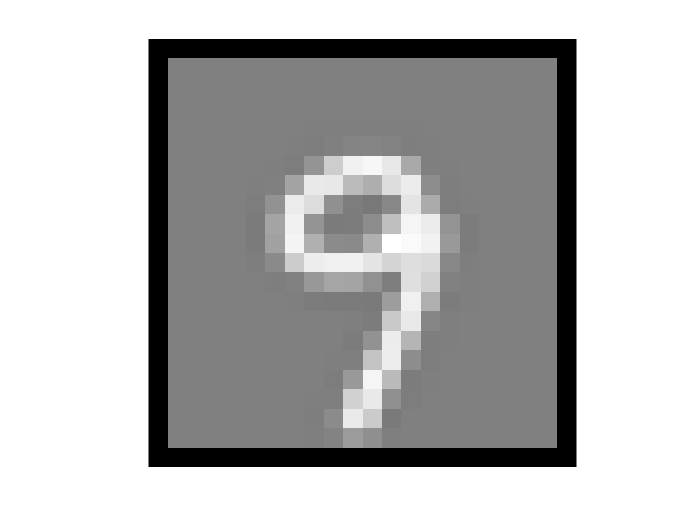

% Display 
displayData(X(rp, :)); 